# (Root) Raised Cosine Filter

This function designs the Impulse Response (i.e., discrete-time pulse shape) of a Raised Cosine (RC) filter and Root Raised Cosine (RRC) filter, typically used for pulse shaping.

**Inputs:**

- *rolloff*: rolloff factor of the raised cosine filter ($0\le \text{rolloff}\le 1  $)

- *span*: pulse impulse response duration in terms of symbols

- *sps*: number of samples per symbol 

- *shape*: select Raised Cosine filter (*shape *= 'normal') or Root Raised Cosine filter (*shape *= 'sqrt')

**Ouput:**

- *g*: Impulse Response (IR) of the pulse of size *1 x ( span . sps + 1 )*

function g = raised_cosine( rolloff , span , sps , shape )
    nb_sample_per_pulse = span * sps ;
    if rem( nb_sample_per_pulse , 2) ~= 0
        error('The product of sps and span must be even')
    end

## Guidelines for the pulse IR design

### General expressions

The pulse shape of a **raised cosine** spectrum is given by the following relationship:


$$g_{RC}\left(t\right)=\text{sinc}\left(\pi t / T\right)\frac{\cos\left( \pi \beta t / T\right)}{1-4 \beta^2 t^2 / T^2}$$


The pulse shape of a **root raised cosine** spectrum is given by the following relationship:


$$g_{RRC}\left(t\right)=\frac{ 4\beta\cos\left[ \left( 1+\beta \right)\pi t / T  \right]+\frac{\sin\left[ \left( 1-\beta \right)\pi t / T  \right]} {\left( t/T\right)}}{ \pi*\sqrt{T} * \left[ 1 - 16 \beta^2t^2/T^2\right]}$$
 

where $\beta$ is the roll-off factor and $T$ is the symbol duration.

### Time truncation

Both $g_{RC}\left(t\right)$and $g_{RRC}\left(t\right)$expressions lead to Infinite Impusle Response (IIR) filters. However, since these pulses decay with time, it is possible to truncate their Impulse Response (IR) without deteriorating too much their spectrum and hence, their Nyquist criterion properties. One obtain therefore Finite Impulse Response (FIR) filters which are more stable (but typically more demanding than IIR filters in terms of computational resources).

We define the $ \text{span}$ of the filter as a parameter to truncate the filter impulse response. The higher the $ \text{span}$, the longer the pulse duration. $ \text{span}$ is expressed in terms of symbols. It is the number of symbols during which the pulse IR lasts. The total pulse duration is therefore equal to $ \text{span}.T $, where $ T $ is the symbol duration. For instance, if $ \text{span}=5$, the pulse impulse response lasts during $ 5T$: 2 symbols before and 2 symbols after the symbol $s_k$ under consideration. The figure below illustrates 2 examples of $ \text{span}$ values used to truncate the pulse.

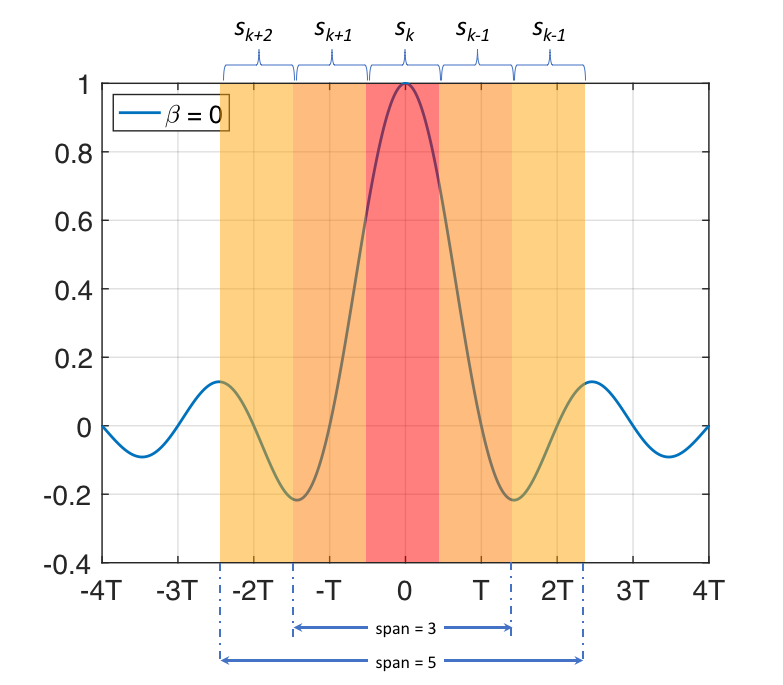

Higher $ \text{span}$ values better approximate the original IIR but requires more computational resources, so a tradeoff is to be chosen. Typical values of impulse response duration are 8-16 symbols. High values of $ \text{span}$ potentially leads to lower ISI at the receiver side. High values are also necessary to reach a certain level of out-of-band attenuation (when the impulse response is truncated in time, the out-ot-band spectrum is no longer perfeclty zero, and exhibits pass-band ripples, a certain slope, and out-of-band sidelobes).

### Discrete time

The expressions given for the pulse shape are in continuous time. The first step is therefore to discritize the time vector such as:

$t=nT_S$, with $T_S$ the sampling time related to the sampling frequency $f_S$ by $T_S=1/f_S$.

By including the truncation, the discrete-time vector can be expressed as:


$$t=-\frac{\text{span}}{2}T:T_S:\frac{\text{span}}{2}T$$


The variable *sps* sets the number of samples per symbol. Thanks to this parametres, oversampling ratio can be easily adjusted. So the symbol duration can be expressed as:


$$T=\text{sps}.T_S$$


Finally, the time domain expressions of the pulses can be expressed with no other parameters than *span* and *sps* in addition to the *rolloff* factor value by observing that:


$$t/T=-\frac{\text{span}}{2}:\frac{1}{\text{sps}}:\frac{\text{span}}{2}$$


The pulse impulse response must contain an odd number of samples equal to *sps.span + 1*. So the product *sps.span* should be even.

**Note for RCC filter!** Even after replacing the vector $t/T$ by the above expression in $g_{RRC}\left(t\right)$, a $\sqrt{T}$ term remains. This constant term can however be simply dropped (e.g., assuming $T=1$) since it only affects the filter amplitude and does not affect its shape. The filter amplitude will be anyway normalized such as to exhibit a unit energy.

**Be carefull!** The sinc function in Matlab does automatically introduce $\pi$in its argument (see the help of the *sinc* function).

## Raised Cosine (RC) filter

When $|t/T|\to \frac{1}{2\beta}$, the $g_{RC}\left(t\right)$expression assumes an indeterminate form. The Matlab result will therefore not be accurate. It is then required to anaytically calculate the limit $\lim_{|t/T| \to \frac{1}{2\beta}} g_{RC}(t)$ and to use the resulting expression to calculate $g_{RC}\left(t\right)$when $|t/T|= \frac{1}{2\beta}$. To calculate this limit, you can use L'Hôpital's rule for the term $\frac{\cos\left( \pi \beta t / T\right)}{1-4 \beta^2 t^2 / T^2}$ in $g_{RC}\left(t\right)$.

**Tips**: At first, choose a rolloff factor $\beta$ value that does not involve $|t/T|=\frac{1}{2\beta}$. In that case, the indeterminate form issue will not raise and you will be able to code the RC filter and to test whether your implementation is correct or not. Once it works, choose a rolloff factor $\beta$ value for which the condition $|t/T|=\frac{1}{2\beta}$ does occur. You will have to calculate manually the limit $\lim_{|t/T| \to \frac{1}{2\beta}} g_{RC}(t)$ and to implement it in order to make your filter impulse response correct again.

if strncmp(shape, 'normal', 1)
    
    t = (-span/2 : 1/sps : span/2); 
    
    % Initialize the impulse response vector
    g = zeros(size(t));
    
    % Calculate the Raised Cosine (RC) impulse response
    for i = 1:length(t)
        if abs(t(i)) == 0
            % Handle the case when t = 0
            g(i) = 1;
        elseif abs(t(i)) == 1/(2*rolloff)
            % Handle the case when t = ±1/(2*rolloff)
            g(i) = (pi/4)*(sinc(1/(2*rolloff)));
        else
            % General case for all other t
            g(i) = sinc((t(i))) * cos(pi * rolloff * t(i)) / (1 - (2 * rolloff * t(i))^2); 
        end
    end



## Root Raised Cosine (RRC) filter

Unlike the raised-cosine filter, the RRC impulse response is not zero at the intervals of ±*Ts*. However, the combined transmit and receive filters form a raised-cosine filter which does have zero at the intervals of ±*Ts*. Only in the case of *β*=0 does the root raised-cosine have zeros at ±*Ts*.

The expression $g_{RRC}\left(t\right)$ assumes an indeterminate form when the vector $t/T$ has the following values:

- $t/T=0$ (use $\sin x \simeq  x$ to calculate the limit)

- $|t/T|=\frac{1}{4\beta}$ (use L'Hôpital's rule to calculate the limit)

Use the expressions found for those limits to implement the calculation of these specific points in Matlab.

**Tips**: Similarly to the implementation of the RC filter, choose a rolloff factor $\beta$ value that does not involve $|t/T|=\frac{1}{4\beta}$ to avoid dealing with this indeterminate form in a first approach. However, you cannot avoid the indeterminate form when $t/T=0$ and should deal with it whatever the rolloff factor $\beta$ value (but this limit is straightforward to calculate).

    elseif strncmp(shape, 'sqrt', 1)
    t = (-span/2 : 1/sps : span/2);
    % Initialize the impulse response vector
    g = zeros(size(t));

    % Calculate the Raised Cosine (RC) impulse response
    for i = 1:length(t)
        if abs(t(i)) == 0
            % Handle the case when t = 0
            g(i) = ( 1 + rolloff * ( (4 / pi) - 1 ) );
        elseif abs(t(i)) == 1/(4*rolloff)

            g(i) = ( rolloff / ( 2^(1/2) ) ) * ( (1 + ( 2 / pi ) ) *sin( pi / ( 4*rolloff ) ) + (1 - 2 / pi ) * cos( pi / ( 4*rolloff ) ) ) ;
        else
            % General case for all other t
            g(i) = ( 4 * rolloff * cos( (1 + rolloff) * pi * t(i) ) + ( sin( (1 - rolloff) * pi * t(i) ) / t(i) )) / ( pi * (1 - ( 16 * rolloff^2 * t(i)^2 ) ) );

        end
    end
end

## Filter Energy Normalization 

The filter amplitude is normalized in order to exhibit a unit energy. With this normalization, the amplitude of a TX symbol will remain constant after passing successively through TX and RX filter (if the propagation channel is not considered, i.e., $h=1$).

    g = g / sqrt( sum( g.^2 ) ) ;                                   
end